**INTERACTIVE TUTORIAL**

# Introduction to different viewing angles in 3D

University of Arizona - Math 313 - Dr. Nicole Fider

Last updated: 7/8/21

## EXAMPLES

The images below show the xy-plane (leftmost plot), and various orientations of the xy-plane in 3-space based on several viewing angles  In each of the 3D images, the z axis is being held steading in a vertical position, and the xy-plane is being spun around the z-axis.  To help you with perspective, the positive half of the x-axis is always colored blue, the positive half of the y-axis is always colored teal, and the positive half of the z-axis is always colored magenta. The negative half of every axis is gray.

Note that per convention, the axis labels in the 3D figures always appear at the end of the positive side of the axis. 

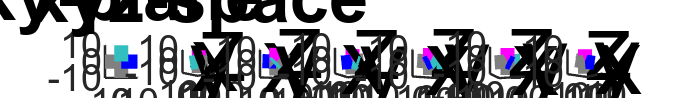


x_range=10;
y_range=10;
z_range=10;

figure;
A=[-130,-170, -210, -250, -290, -320];
len=length(A);
subplot(1,len+1,1);hold on; grid off; 
    plot([-1*x_range 0],[0 0],'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot([0 0],[-1*y_range 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot([0 x_range],[0 0],'LineWidth',3, 'Color', [0 0 1]);
    plot([0 0],[0 y_range],'LineWidth',3, 'Color', [0.2 .75 .75]);
    title('xy-plane', 'FontSize',15)
    pbaspect([1 1 1])
for i=1:len
    %SUBPLOT
    subplot(1,len+1,i+1);
    hold on; grid off; 
    % --- Set axis limits
    xlim([-1*x_range x_range]); ylim([-1*y_range y_range]); zlim([-1*z_range z_range]);
    % --- Label and plot each axis 
    text(x_range+0.5,0,0,'x', 'FontSize',20); text(0,y_range+0.5,0,'y', 'FontSize',20); text(0,0,y_range+0.5,'z', 'FontSize',20);
    plot3([-1*x_range 0],[0 0],[ 0 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 0],[-1*y_range 0],[ 0 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 0],[ 0 0], [-1*z_range 0],'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 x_range],[0 0],[ 0 0], 'LineWidth',3, 'Color', [0 0 1]);
    plot3([0 0],[0 y_range],[ 0 0], 'LineWidth',3, 'Color', [0.2 .75 .75]);
    plot3([0 0],[ 0 0], [0 z_range],'LineWidth',3, 'Color', 'm');
    % --- Graph title, view angle, and grid spacing
    if i==1
        title('xyz-space', 'FontSize',15)
    end
    view([A(i),10])
    pbaspect([1 1 1])
end
set(gcf,'Position',[100 100 200*(len+1) 200])

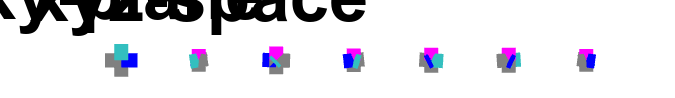

figure;
A=[-130,-170, -210, -250, -290, -320];
len=length(A);
subplot(1,len+1,1);hold on; grid off; axis off;
    plot([-1*x_range 0],[0 0],'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot([0 0],[-1*y_range 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot([0 x_range],[0 0],'LineWidth',3, 'Color', [0 0 1]);
    plot([0 0],[0 y_range],'LineWidth',3, 'Color', [0.2 .75 .75]);
    title('xy-plane', 'FontSize',15)
    pbaspect([1 1 1])
for i=1:len
    %SUBPLOT
    subplot(1,len+1,i+1);
    % --- Plot three planes
    hold on; grid off; axis off;
    % --- Set axis limits
    xlim([-1*x_range x_range]); ylim([-1*y_range y_range]); zlim([-1*z_range z_range]);
    % --- Plot each axis, without labels
    plot3([-1*x_range 0],[0 0],[ 0 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 0],[-1*y_range 0],[ 0 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 0],[ 0 0], [-1*z_range 0],'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 x_range],[0 0],[ 0 0], 'LineWidth',3, 'Color', [0 0 1]);
    plot3([0 0],[0 y_range],[ 0 0], 'LineWidth',3, 'Color', [0.2 .75 .75]);
    plot3([0 0],[ 0 0], [0 z_range],'LineWidth',3, 'Color', 'm');
    % --- Graph title, view angle, and grid spacing
    if i==1
        title('xyz-space', 'FontSize',15)
    end
    view([A(i),10])
    pbaspect([1 1 1])
end
set(gcf,'Position',[100 100 200*(len+1) 200])

## INTERACTIVE FIGURE

Use this interactive figure to view the xyz-axes from even more perspectives.

First, rotate the image clockwise about the z-axis by setting the variable CWZ; type the number of degrees (positive or negative) you would like to rotate. **Reccomended values are 30, 60, 120, 150, 210, 240.**

- Enter 0 to get $0^{\circ \;}$rotation about the z-axis.  This means the the positive half of the y-axis is going into the screen directly away from you, while the negative half of the y-axis is coming out of the screen directly towards you. The positive half of the x-axis goes to the right, as usual.

- Enter 90 to get ${90}^{\circ \;}$ rotation about the z-axis.  This swivels the xy-plane so that means the positive half of the y-axis is going to the right.  The positive half of the x-axis is coming out of the screen directly towards you.

- Enter 180 to get ${180}^{\circ \;}$ rotation about the z-axis.  This swivels the xy-plane so that means the positive half of the y-axis is going straight out of the screen towards you.  The positive half of the x-axis is pointing to the left. 

- Etc. Reccomended values are

Second, tilt the image up or down by setting the variable UD; type the number of degrees (positive or negative) you would like to rotate.  **20 is reccommended.**

- To set your viewing angle level to the xy-plane, so that the xy-plane appears as a horizontal line, use 0.

- To view the xy=plane from above, choose a number between 0 and 90

- To view the xy=plane from above, choose a number between -90 and 0

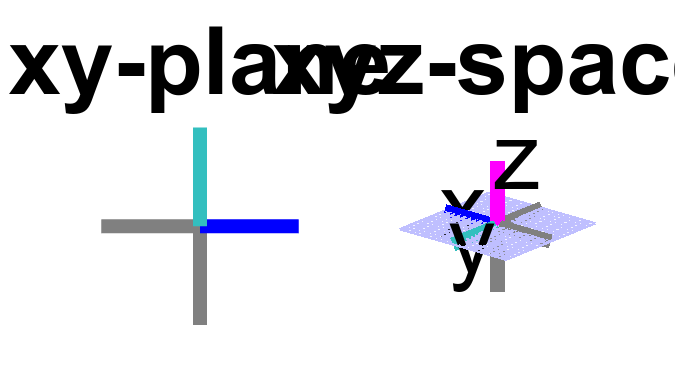

CWZ=220;
UD=20;
 

ViewAngle=[CWZ,UD];

x_range=10; y_range=10; z_range=10;
figure;
subplot(1,2,1); hold on; grid off; axis off;
    plot([-1*x_range 0],[0 0],'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot([0 0],[-1*y_range 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot([0 x_range],[0 0],'LineWidth',3, 'Color', [0 0 1]);
    plot([0 0],[0 y_range],'LineWidth',3, 'Color', [0.2 .75 .75]);
    title('xy-plane', 'FontSize',20)
    pbaspect([1 1 1])
subplot(1,2,2); hold on; grid off; axis off;
    % --- Make grid on xy-plane
    [X,Y] = meshgrid(-1*x_range:1:x_range, -1*y_range:1:y_range);
    P=0*X;
    surf(X,Y,P, 'FaceAlpha', 0.2, 'EdgeColor', [0.75 .75 1], 'FaceColor',[0.75 .75 1], 'LineWidth',0.5);

    % --- Set axis limits
    xlim([-1*x_range x_range]); ylim([-1*y_range y_range]); zlim([-1*z_range z_range]);
    % --- Plot each axis, with labels
    text(x_range+0.5,0.5,0.5,'x', 'FontSize',20); 
    text(0.5,y_range+0.5,0.5,'y', 'FontSize',20); 
    text(0.5,0.5,y_range+0.5,'z', 'FontSize',20);
    plot3([-1*x_range 0],[0 0],[ 0 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 0],[-1*y_range 0],[ 0 0], 'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 0],[ 0 0], [-1*z_range 0],'LineWidth',3, 'Color', 0.5*[1 1 1]);
    plot3([0 x_range],[0 0],[ 0 0], 'LineWidth',3, 'Color', [0 0 1]);
    plot3([0 0],[0 y_range],[ 0 0], 'LineWidth',3, 'Color', [0.2 .75 .75]);
    plot3([0 0],[ 0 0], [0 z_range],'LineWidth',3, 'Color', 'm');
    % --- Graph title, view angle, and grid spacing
    title('xyz-space', 'FontSize',20)
    view(ViewAngle)
    pbaspect([1 1 1])
    

set(gcf,'Position',[100 100 900 500])